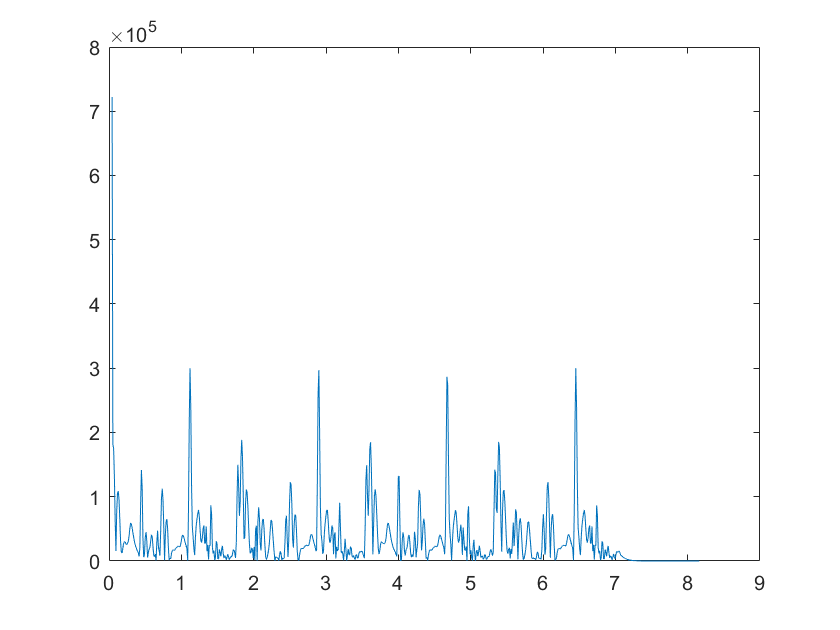

newTime =     0.0427    0.0533    0.0640    0.0747    0.0853    0.0960    0.1067    0.1173    0.1280    0.1387    0.1493    0.1600    0.1707    0.1813    0.1920    0.2027    0.2133    0.2240    0.2347    0.2453    0.2560    0.2667    0.2773    0.2880    0.2987    0.3093    0.3200    0.3307    0.3413    0.3520    0.3627    0.3733    0.3840    0.3947    0.4053    0.4160    0.4267    0.4373    0.4480    0.4587    0.4693    0.4800    0.4907    0.5013    0.5120    0.5227    0.5333    0.5440    0.5547    0.5653


HFCDiff = 	1.0e+05 *

    7.2225    1.8139    1.7560    1.2998    0.6244    0.1565    0.7696    1.0473    1.0883    0.9536    0.6485    0.3095    0.1293    0.1272    0.2061    0.2761    0.3001    0.2952    0.2650    0.2566    0.2728    0.3077    0.3862    0.5038    0.5914    0.5801    0.5139    0.4385    0.3690    0.3033    0.2496    0.2123    0.1806    0.1543    0.1296    0.0709    0.2095    0.8835    1.4164    1.1314    0.3461    0.0583    0.1116    0.3697    0.4485    0.3070    0.0524    0.1326    0.1846    0.2078


wav = 'AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav';

FFTSize = 4096;
hopSize = 512;
[newTime,HFCDiff] = Noctones_HFCDiff(wav,FFTSize,hopSize)

realLocsResized =     39    66    72   102   129   144   164   169   191   207   227   232   269   296   310   331   336   373   399   405   435   463   477   497   502   524   541   560   566   572   602   629   644   658   758


peaksPos =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


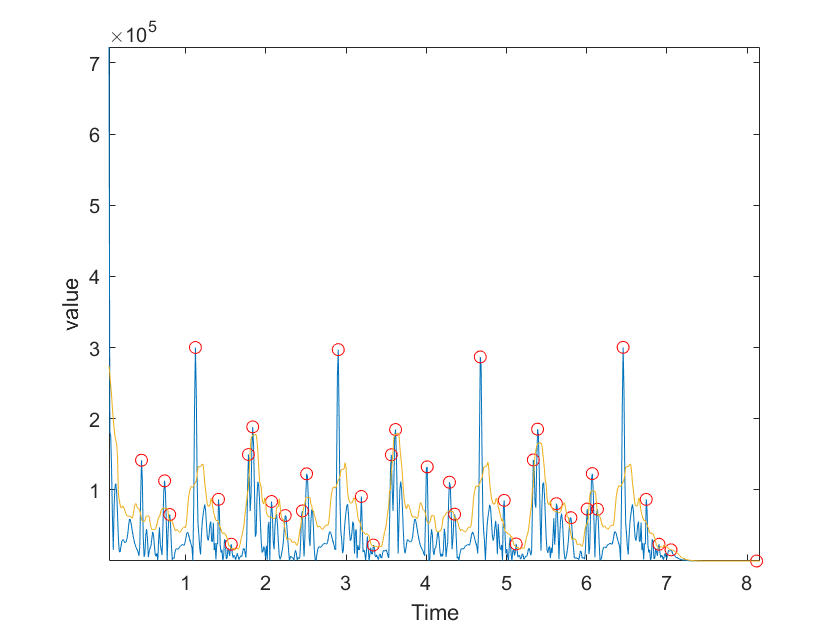

peaks =     0.4480    0.7360    0.8000    1.1200    1.4080    1.5680    1.7813    1.8347    2.0693    2.2400    2.4533    2.5067    2.9013    3.1893    3.3387    3.5627    3.6160    4.0107    4.2880    4.3520    4.6720    4.9707    5.1200    5.3333    5.3867    5.6213    5.8027    6.0053    6.0693    6.1333    6.4533    6.7413    6.9013    7.0507    8.1173


peaks = Noctones_FindPeaks(newTime,HFCDiff,20)

[RMSTab,events] = Noctones_RMS(wav, FFTSize,hopSize)

Computing miraudio related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Computing mirsum related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Elapsed time is 1.092290 seconds.
Computing mirrms related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Computing mironsets related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Computing mirsum related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Computing mirpeaks related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...


RMSTab =     0.0622    0.0677    0.0717    0.0749    0.0778    0.0778    0.0779    0.0753    0.0728    0.0700    0.0681    0.0668    0.0642    0.0639    0.0627    0.0617    0.0610    0.0600    0.0590    0.0567    0.0557    0.0535    0.0512    0.0490    0.0463    0.0435    0.0397    0.0371    0.0339    0.0312    0.0288    0.0266    0.0246    0.0223    0.0222    0.0302    0.0347    0.0385    0.0422    0.0460    0.0509    0.0559    0.0604    0.0607    0.0620    0.0638    0.0651    0.0656    0.0649    0.0636


events =     0.0588
    0.5004
    0.7332
    1.1288
    1.3435
    1.8324
    2.0582
    2.3008
    2.3278
    2.5081


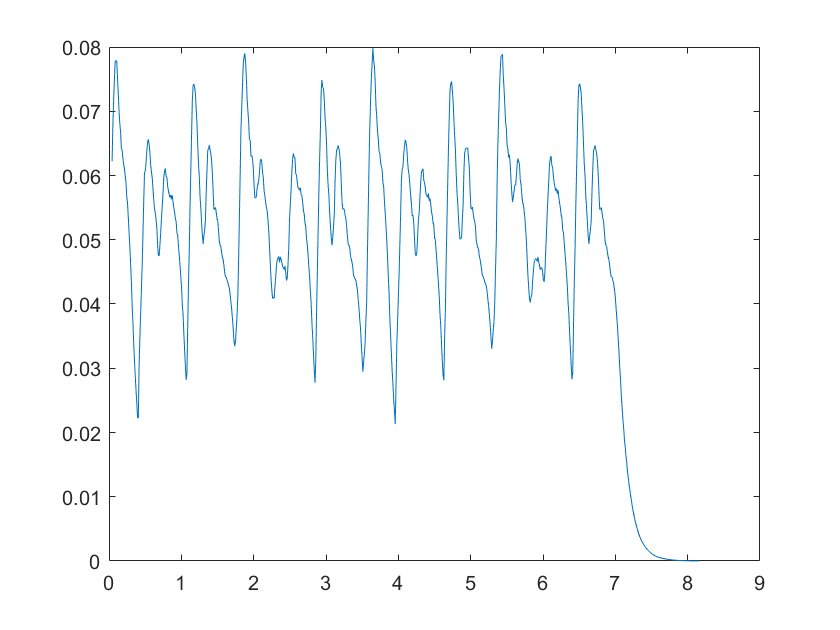


plot(newTime,RMSTab)